# **Práctica 1: Introducción a la Wavelet Toolbox de MATLAB**

## **Ejercicio 1. Generar señales. **

***Crear señales de longitud 2048 que representen cada función en el intervalo [0,1]. Representarlas gráficamente.***

% Generar el intervalo [0,1] de longitud 2048
x = linspace(0,1,2048);

**1) **$f(x)=1$

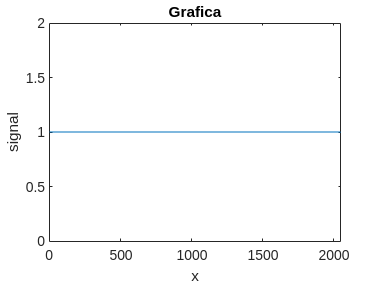

% Crear la señal 
fx1 = ones(size(x));

% Gráficar
plot(fx1)
title('Grafica')
xlabel('x')
ylabel('signal')
axis([0 length(fx1) min(fx1)-1 max(fx1)+1])

**2) **$f(x)=x^2(1-x)$

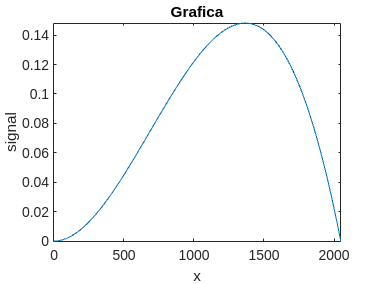

% Crear la señal 
fx2 = x.^2.*(1-x);

% Gráficar
plot(fx2)
title('Grafica')
xlabel('x')
ylabel('signal')
axis([0 length(fx2) min(fx2) max(fx2)])

**3) **$f(x)=x^4(1-x)^6\cos(64\pi x)$

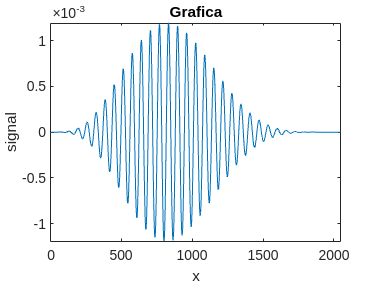

% Crear la señal 
fx3 = x.^4.*(1-x).^6.*cos(64*pi*x);

% Gráficar
plot(fx3)
title('Grafica')
xlabel('x')
ylabel('signal')
axis([0 length(fx3) min(fx3) max(fx3)])

**4) **$f (x) = 1(0,2 < x < 0,3) - 3(0,4 < x < 0,5) + 2(0,5 < x < 0,8)$

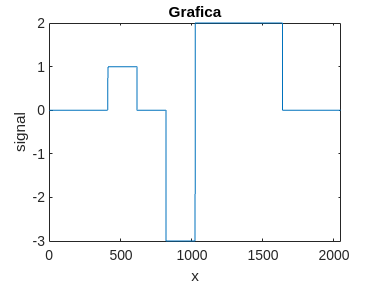

% Crear la señal
fx4 = zeros(size(x));
fx4((0.2 < x) & (x < 0.3)) = 1;
fx4((0.4 < x) & (x < 0.5)) = -3;
fx4((0.5 < x) & (x < 0.8)) = 2;

% Gráficar
plot(fx4)
title('Grafica')
xlabel('x')
ylabel('signal')
axis([0 length(fx4) min(fx4) max(fx4)])

**5) **$f (x) = sign(\sin(12\pi x))$

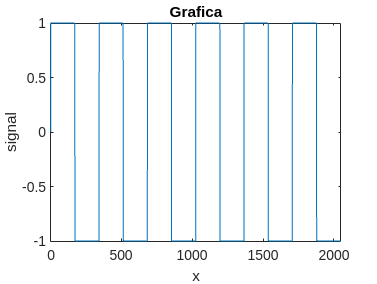

% Crear la señal 
fx5 = sign(sin(12*pi*x));

% Gráficar
plot(fx5)
title('Grafica')
xlabel('x')
ylabel('signal')
axis([0 length(fx5) min(fx5) max(fx5)])

## Ejercicio 2. Análisis Wavelet.

**Para cada una de las señales anteriores realizar las siguientes tareas utilizando diferentes wavelets y comparar los resultados.**

- ***Calcular la transformada wavelet de nivel 1. Obtener las subseñales tendencia y fluctuación. Representar gráficamente.***

**1) **$f(x)=1$

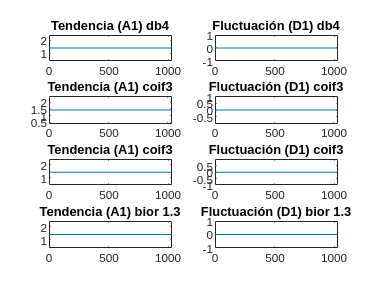

% Calculamos algunas transformadas wavelet

% Nivel 1
s = fx1;                                                % Señal
wdb4 = 'db4';                                           % Daubechies
wcoif3 = 'coif3';                                       % Coiflets
wsym5 = 'sym5';                                         % Symlets
wbior1_3 = 'bior1.3';                                   % Biorthogonal


% Transformadas
[Cdb4,Ldb4] = wavedec(s,1,wdb4);                        % Daubechies
[Ccoif3,Lcoif3] = wavedec(s,1,wcoif3);                  % Coiflets
[Csym5,Lsym5] = wavedec(s,1,wsym5);                     % Symlets
[Cbior1_3,Lbior1_3] = wavedec(s,1,wbior1_3);            % Biorthogonal


% Subseñales de tendencia y fluctiación (coeficientes)
cdb4_A1 = appcoef(Cdb4,Ldb4,wdb4,1);                    % Daubechies
cdb4_D1 = detcoef(Cdb4,Ldb4,1);                         % Daubechies

ccoif3_A1 = appcoef(Ccoif3,Lcoif3,wcoif3,1);            % Coiflets
ccoif3_D1 = detcoef(Ccoif3,Lcoif3,1);                   % Coiflets

csym5_A1 = appcoef(Csym5,Lsym5,wsym5,1);                % Symlets
csym5_D1 = detcoef(Csym5,Lsym5,1);                      % Symlets

cbior1_3_A1 = appcoef(Cbior1_3,Lbior1_3,wbior1_3,1);    % Biorthogonal
cbior1_3_D1 = detcoef(Cbior1_3,Lbior1_3,1);             % Biorthogonal


% Plots
figure; 
% Daubechies
subplot(4,2,1)
plot(cdb4_A1);title('Tendencia (A1) db4')
axis([0 length(cdb4_A1) min(cdb4_A1)-1 max(cdb4_A1)+1]);
subplot(4,2,2)
plot(cdb4_D1);title('Fluctuación (D1) db4')
axis([0 length(cdb4_D1) min(cdb4_D1)-1 max(cdb4_D1)+1]);

% Coiflets
subplot(4,2,3)
plot(ccoif3_A1);title('Tendencia (A1) coif3')
axis([0 length(ccoif3_A1) min(ccoif3_A1)-1 max(ccoif3_A1)+1]);
subplot(4,2,4)
plot(ccoif3_D1);title('Fluctuación (D1) coif3')
axis([0 length(ccoif3_D1) min(ccoif3_D1)-1 max(ccoif3_D1)+1]);

% Coiflets
subplot(4,2,5)
plot(csym5_A1);title('Tendencia (A1) coif3')
axis([0 length(csym5_A1) min(csym5_A1)-1 max(csym5_A1)+1]);
subplot(4,2,6)
plot(csym5_D1);title('Fluctuación (D1) coif3')
axis([0 length(csym5_D1) min(csym5_D1)-1 max(csym5_D1)+1]);

% Biorthogonal
subplot(4,2,7)
plot(cbior1_3_A1);title('Tendencia (A1) bior 1.3')
axis([0 length(cbior1_3_A1) min(cbior1_3_A1)-1 max(cbior1_3_A1)+1]);
subplot(4,2,8)
plot(cbior1_3_D1);title('Fluctuación (D1) bior 1.3')
axis([0 length(cbior1_3_D1) min(cbior1_3_D1)-1 max(cbior1_3_D1)+1]);

**2) **$f(x)=x^2(1-x)$

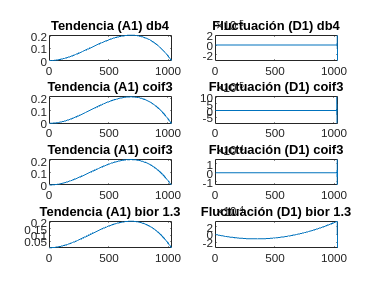

% Calculamos algunas transformadas wavelet

% Nivel 1
s = fx2;                                                % Señal
wdb4 = 'db4';                                           % Daubechies
wcoif3 = 'coif3';                                       % Coiflets
wsym5 = 'sym5';                                         % Symlets
wbior1_3 = 'bior1.3';                                   % Biorthogonal


% Transformadas
[Cdb4,Ldb4] = wavedec(s,1,wdb4);                        % Daubechies
[Ccoif3,Lcoif3] = wavedec(s,1,wcoif3);                  % Coiflets
[Csym5,Lsym5] = wavedec(s,1,wsym5);                     % Symlets
[Cbior1_3,Lbior1_3] = wavedec(s,1,wbior1_3);            % Biorthogonal


% Subseñales de tendencia y fluctiación (coeficientes)
cdb4_A1 = appcoef(Cdb4,Ldb4,wdb4,1);                    % Daubechies
cdb4_D1 = detcoef(Cdb4,Ldb4,1);                         % Daubechies

ccoif3_A1 = appcoef(Ccoif3,Lcoif3,wcoif3,1);            % Coiflets
ccoif3_D1 = detcoef(Ccoif3,Lcoif3,1);                   % Coiflets

csym5_A1 = appcoef(Csym5,Lsym5,wsym5,1);                % Symlets
csym5_D1 = detcoef(Csym5,Lsym5,1);                      % Symlets

cbior1_3_A1 = appcoef(Cbior1_3,Lbior1_3,wbior1_3,1);    % Biorthogonal
cbior1_3_D1 = detcoef(Cbior1_3,Lbior1_3,1);             % Biorthogonal


% Plots
figure; 
% Daubechies
subplot(4,2,1)
plot(cdb4_A1);title('Tendencia (A1) db4')
axis([0 length(cdb4_A1) min(cdb4_A1) max(cdb4_A1)]);
subplot(4,2,2)
plot(cdb4_D1);title('Fluctuación (D1) db4')
axis([0 length(cdb4_D1) min(cdb4_D1) max(cdb4_D1)]);

% Coiflets
subplot(4,2,3)
plot(ccoif3_A1);title('Tendencia (A1) coif3')
axis([0 length(ccoif3_A1) min(ccoif3_A1) max(ccoif3_A1)]);
subplot(4,2,4)
plot(ccoif3_D1);title('Fluctuación (D1) coif3')
axis([0 length(ccoif3_D1) min(ccoif3_D1) max(ccoif3_D1)]);

% Coiflets
subplot(4,2,5)
plot(csym5_A1);title('Tendencia (A1) coif3')
axis([0 length(csym5_A1) min(csym5_A1) max(csym5_A1)]);
subplot(4,2,6)
plot(csym5_D1);title('Fluctuación (D1) coif3')
axis([0 length(csym5_D1) min(csym5_D1) max(csym5_D1)]);

% Biorthogonal
subplot(4,2,7)
plot(cbior1_3_A1);title('Tendencia (A1) bior 1.3')
axis([0 length(cbior1_3_A1) min(cbior1_3_A1) max(cbior1_3_A1)]);
subplot(4,2,8)
plot(cbior1_3_D1);title('Fluctuación (D1) bior 1.3')
axis([0 length(cbior1_3_D1) min(cbior1_3_D1) max(cbior1_3_D1)]);

**3) **$f(x)=x^4(1-x)^6\cos(64\pi x)$

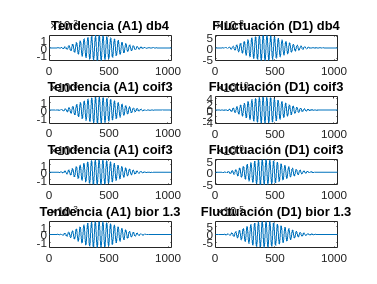

% Calculamos algunas transformadas wavelet

% Nivel 1
s = fx3;                                                % Señal
wdb4 = 'db4';                                           % Daubechies
wcoif3 = 'coif3';                                       % Coiflets
wsym5 = 'sym5';                                         % Symlets
wbior1_3 = 'bior1.3';                                   % Biorthogonal


% Transformadas
[Cdb4,Ldb4] = wavedec(s,1,wdb4);                        % Daubechies
[Ccoif3,Lcoif3] = wavedec(s,1,wcoif3);                  % Coiflets
[Csym5,Lsym5] = wavedec(s,1,wsym5);                     % Symlets
[Cbior1_3,Lbior1_3] = wavedec(s,1,wbior1_3);            % Biorthogonal


% Subseñales de tendencia y fluctiación (coeficientes)
cdb4_A1 = appcoef(Cdb4,Ldb4,wdb4,1);                    % Daubechies
cdb4_D1 = detcoef(Cdb4,Ldb4,1);                         % Daubechies

ccoif3_A1 = appcoef(Ccoif3,Lcoif3,wcoif3,1);            % Coiflets
ccoif3_D1 = detcoef(Ccoif3,Lcoif3,1);                   % Coiflets

csym5_A1 = appcoef(Csym5,Lsym5,wsym5,1);                % Symlets
csym5_D1 = detcoef(Csym5,Lsym5,1);                      % Symlets

cbior1_3_A1 = appcoef(Cbior1_3,Lbior1_3,wbior1_3,1);    % Biorthogonal
cbior1_3_D1 = detcoef(Cbior1_3,Lbior1_3,1);             % Biorthogonal


% Plots
figure; 
% Daubechies
subplot(4,2,1)
plot(cdb4_A1);title('Tendencia (A1) db4')
axis([0 length(cdb4_A1) min(cdb4_A1) max(cdb4_A1)]);
subplot(4,2,2)
plot(cdb4_D1);title('Fluctuación (D1) db4')
axis([0 length(cdb4_D1) min(cdb4_D1) max(cdb4_D1)]);

% Coiflets
subplot(4,2,3)
plot(ccoif3_A1);title('Tendencia (A1) coif3')
axis([0 length(ccoif3_A1) min(ccoif3_A1) max(ccoif3_A1)]);
subplot(4,2,4)
plot(ccoif3_D1);title('Fluctuación (D1) coif3')
axis([0 length(ccoif3_D1) min(ccoif3_D1) max(ccoif3_D1)]);

% Coiflets
subplot(4,2,5)
plot(csym5_A1);title('Tendencia (A1) coif3')
axis([0 length(csym5_A1) min(csym5_A1) max(csym5_A1)]);
subplot(4,2,6)
plot(csym5_D1);title('Fluctuación (D1) coif3')
axis([0 length(csym5_D1) min(csym5_D1) max(csym5_D1)]);

% Biorthogonal
subplot(4,2,7)
plot(cbior1_3_A1);title('Tendencia (A1) bior 1.3')
axis([0 length(cbior1_3_A1) min(cbior1_3_A1) max(cbior1_3_A1)]);
subplot(4,2,8)
plot(cbior1_3_D1);title('Fluctuación (D1) bior 1.3')
axis([0 length(cbior1_3_D1) min(cbior1_3_D1) max(cbior1_3_D1)]);

**4) **$f (x) = 1(0,2 < x < 0,3) - 3(0,4 < x < 0,5) + 2(0,5 < x < 0,8)$

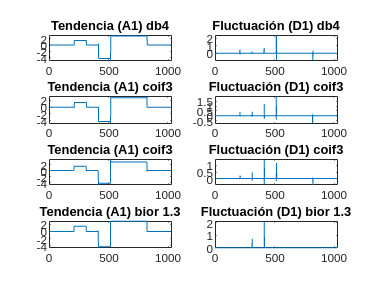

% Calculamos algunas transformadas wavelet

% Nivel 1
s = fx4;                                                % Señal
wdb4 = 'db4';                                           % Daubechies
wcoif3 = 'coif3';                                       % Coiflets
wsym5 = 'sym5';                                         % Symlets
wbior1_3 = 'bior1.3';                                   % Biorthogonal


% Transformadas
[Cdb4,Ldb4] = wavedec(s,1,wdb4);                        % Daubechies
[Ccoif3,Lcoif3] = wavedec(s,1,wcoif3);                  % Coiflets
[Csym5,Lsym5] = wavedec(s,1,wsym5);                     % Symlets
[Cbior1_3,Lbior1_3] = wavedec(s,1,wbior1_3);            % Biorthogonal


% Subseñales de tendencia y fluctiación (coeficientes)
cdb4_A1 = appcoef(Cdb4,Ldb4,wdb4,1);                    % Daubechies
cdb4_D1 = detcoef(Cdb4,Ldb4,1);                         % Daubechies

ccoif3_A1 = appcoef(Ccoif3,Lcoif3,wcoif3,1);            % Coiflets
ccoif3_D1 = detcoef(Ccoif3,Lcoif3,1);                   % Coiflets

csym5_A1 = appcoef(Csym5,Lsym5,wsym5,1);                % Symlets
csym5_D1 = detcoef(Csym5,Lsym5,1);                      % Symlets

cbior1_3_A1 = appcoef(Cbior1_3,Lbior1_3,wbior1_3,1);    % Biorthogonal
cbior1_3_D1 = detcoef(Cbior1_3,Lbior1_3,1);             % Biorthogonal


% Plots
figure; 
% Daubechies
subplot(4,2,1)
plot(cdb4_A1);title('Tendencia (A1) db4')
axis([0 length(cdb4_A1) min(cdb4_A1) max(cdb4_A1)]);
subplot(4,2,2)
plot(cdb4_D1);title('Fluctuación (D1) db4')
axis([0 length(cdb4_D1) min(cdb4_D1) max(cdb4_D1)]);

% Coiflets
subplot(4,2,3)
plot(ccoif3_A1);title('Tendencia (A1) coif3')
axis([0 length(ccoif3_A1) min(ccoif3_A1) max(ccoif3_A1)]);
subplot(4,2,4)
plot(ccoif3_D1);title('Fluctuación (D1) coif3')
axis([0 length(ccoif3_D1) min(ccoif3_D1) max(ccoif3_D1)]);

% Coiflets
subplot(4,2,5)
plot(csym5_A1);title('Tendencia (A1) coif3')
axis([0 length(csym5_A1) min(csym5_A1) max(csym5_A1)]);
subplot(4,2,6)
plot(csym5_D1);title('Fluctuación (D1) coif3')
axis([0 length(csym5_D1) min(csym5_D1) max(csym5_D1)]);

% Biorthogonal
subplot(4,2,7)
plot(cbior1_3_A1);title('Tendencia (A1) bior 1.3')
axis([0 length(cbior1_3_A1) min(cbior1_3_A1) max(cbior1_3_A1)]);
subplot(4,2,8)
plot(cbior1_3_D1);title('Fluctuación (D1) bior 1.3')
axis([0 length(cbior1_3_D1) min(cbior1_3_D1) max(cbior1_3_D1)]);

**5) **$f (x) = sign(\sin(12\pi x))$

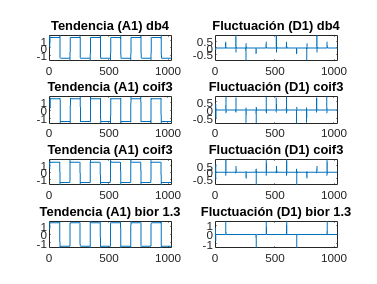

% Calculamos algunas transformadas wavelet

% Nivel 1
s = fx5;                                                % Señal
wdb4 = 'db4';                                           % Daubechies
wcoif3 = 'coif3';                                       % Coiflets
wsym5 = 'sym5';                                         % Symlets
wbior1_3 = 'bior1.3';                                   % Biorthogonal


% Transformadas
[Cdb4,Ldb4] = wavedec(s,1,wdb4);                        % Daubechies
[Ccoif3,Lcoif3] = wavedec(s,1,wcoif3);                  % Coiflets
[Csym5,Lsym5] = wavedec(s,1,wsym5);                     % Symlets
[Cbior1_3,Lbior1_3] = wavedec(s,1,wbior1_3);            % Biorthogonal


% Subseñales de tendencia y fluctiación (coeficientes)
cdb4_A1 = appcoef(Cdb4,Ldb4,wdb4,1);                    % Daubechies
cdb4_D1 = detcoef(Cdb4,Ldb4,1);                         % Daubechies

ccoif3_A1 = appcoef(Ccoif3,Lcoif3,wcoif3,1);            % Coiflets
ccoif3_D1 = detcoef(Ccoif3,Lcoif3,1);                   % Coiflets

csym5_A1 = appcoef(Csym5,Lsym5,wsym5,1);                % Symlets
csym5_D1 = detcoef(Csym5,Lsym5,1);                      % Symlets

cbior1_3_A1 = appcoef(Cbior1_3,Lbior1_3,wbior1_3,1);    % Biorthogonal
cbior1_3_D1 = detcoef(Cbior1_3,Lbior1_3,1);             % Biorthogonal


% Plots
figure; 
% Daubechies
subplot(4,2,1)
plot(cdb4_A1);title('Tendencia (A1) db4')
axis([0 length(cdb4_A1) min(cdb4_A1) max(cdb4_A1)]);
subplot(4,2,2)
plot(cdb4_D1);title('Fluctuación (D1) db4')
axis([0 length(cdb4_D1) min(cdb4_D1) max(cdb4_D1)]);

% Coiflets
subplot(4,2,3)
plot(ccoif3_A1);title('Tendencia (A1) coif3')
axis([0 length(ccoif3_A1) min(ccoif3_A1) max(ccoif3_A1)]);
subplot(4,2,4)
plot(ccoif3_D1);title('Fluctuación (D1) coif3')
axis([0 length(ccoif3_D1) min(ccoif3_D1) max(ccoif3_D1)]);

% Coiflets
subplot(4,2,5)
plot(csym5_A1);title('Tendencia (A1) coif3')
axis([0 length(csym5_A1) min(csym5_A1) max(csym5_A1)]);
subplot(4,2,6)
plot(csym5_D1);title('Fluctuación (D1) coif3')
axis([0 length(csym5_D1) min(csym5_D1) max(csym5_D1)]);

% Biorthogonal
subplot(4,2,7)
plot(cbior1_3_A1);title('Tendencia (A1) bior 1.3')
axis([0 length(cbior1_3_A1) min(cbior1_3_A1) max(cbior1_3_A1)]);
subplot(4,2,8)
plot(cbior1_3_D1);title('Fluctuación (D1) bior 1.3')
axis([0 length(cbior1_3_D1) min(cbior1_3_D1) max(cbior1_3_D1)]);

- ***Calcular la energia y representar los perfiles de energia acumulada de la señal original y de la transfomada.***

- ***Hacer el an*****á*****lisis de multirresolución de la señal: a) obtener las señales de aproximación y detalle A1 y D1; b) reconstruir la señal como s=A1 + D1***

- ***Reconstruir la señal original con la transformada wavelet inversa. Comparar gráficamente las dos formas de reconstrucción.***

**1) **$f(x)=1$

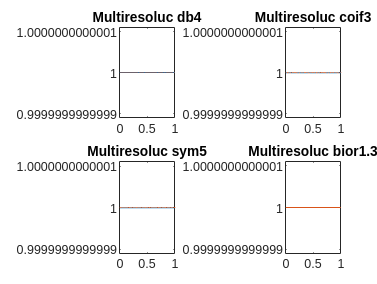

% a) Obtener las señales de aproximación y detalle A1 y D1

% Función

s = fx1;

% Daubechies
wdb4 = 'db4';
[Cdb4,Ldb4] = wavedec(s,1,wdb4);                         
A1_db4 = wrcoef('a',Cdb4,Ldb4,wdb4,1);
D1_db4 = wrcoef('d',Cdb4,Ldb4,wdb4,1);

% Coiflets
wcoif3 = 'coif3';                                      
[Ccoif3,Lcoif3] = wavedec(s,1,wcoif3);                                    
A1_coif3 = wrcoef('a',Ccoif3,Lcoif3,wcoif3,1);
D1_coif3 = wrcoef('d',Ccoif3,Lcoif3,wcoif3,1);

% Symlets
wsym5 = 'sym5';                                         
[Csym5,Lsym5] = wavedec(s,1,wsym5);                                        
A1_sym5 = wrcoef('a',Csym5,Lsym5,wsym5,1);
D1_sym5 = wrcoef('d',Csym5,Lsym5,wsym5,1);

% Biorthogonal   
wbior1_3 = 'bior1.3';
[Cbior1_3,Lbior1_3] = wavedec(s,1,wbior1_3);             
A1_bior1_3 = wrcoef('a',Cbior1_3,Lbior1_3,wbior1_3,1);
D1_bior1_3 = wrcoef('d',Cbior1_3,Lbior1_3,wbior1_3,1);



% b) Reconstruir la señal como s=A1 + D1

% Daubechies
R_db4 = A1_db4 + D1_db4;

% Coiflets
R_coif3 = A1_coif3 + D1_coif3;

% Symlets
R_sym5 = A1_sym5 + D1_sym5;

% Biorthogonal 
R_bior1_3 = A1_bior1_3 + D1_bior1_3;


% PLOTS
figure; 
subplot(2,2,1)
plot(x,s,x,R_db4); title('Multiresoluc db4')

subplot(2,2,2)
plot(x,s,x,R_coif3); title('Multiresoluc coif3')

subplot(2,2,3)
plot(x,s,x,R_sym5); title('Multiresoluc sym5')

subplot(2,2,4)
plot(x,s,x,R_bior1_3); title('Multiresoluc bior1.3')

**2) **$f(x)=x^2(1-x)$

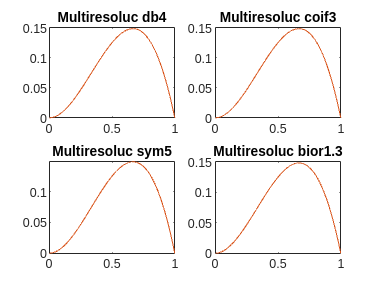

% a) Obtener las señales de aproximación y detalle A1 y D1

% Función
s = fx2;

% Daubechies
wdb4 = 'db4';
[Cdb4,Ldb4] = wavedec(s,1,wdb4);                         
A1_db4 = wrcoef('a',Cdb4,Ldb4,wdb4,1);
D1_db4 = wrcoef('d',Cdb4,Ldb4,wdb4,1);

% Coiflets
wcoif3 = 'coif3';                                      
[Ccoif3,Lcoif3] = wavedec(s,1,wcoif3);                                    
A1_coif3 = wrcoef('a',Ccoif3,Lcoif3,wcoif3,1);
D1_coif3 = wrcoef('d',Ccoif3,Lcoif3,wcoif3,1);

% Symlets
wsym5 = 'sym5';                                         
[Csym5,Lsym5] = wavedec(s,1,wsym5);                                        
A1_sym5 = wrcoef('a',Csym5,Lsym5,wsym5,1);
D1_sym5 = wrcoef('d',Csym5,Lsym5,wsym5,1);

% Biorthogonal   
wbior1_3 = 'bior1.3';
[Cbior1_3,Lbior1_3] = wavedec(s,1,wbior1_3);             
A1_bior1_3 = wrcoef('a',Cbior1_3,Lbior1_3,wbior1_3,1);
D1_bior1_3 = wrcoef('d',Cbior1_3,Lbior1_3,wbior1_3,1);



% b) Reconstruir la señal como s=A1 + D1

% Daubechies
R_db4 = A1_db4 + D1_db4;

% Coiflets
R_coif3 = A1_coif3 + D1_coif3;

% Symlets
R_sym5 = A1_sym5 + D1_sym5;

% Biorthogonal 
R_bior1_3 = A1_bior1_3 + D1_bior1_3;


% PLOTS
figure; 
subplot(2,2,1)
plot(x,s,x,R_db4); title('Multiresoluc db4')

subplot(2,2,2)
plot(x,s,x,R_coif3); title('Multiresoluc coif3')

subplot(2,2,3)
plot(x,s,x,R_sym5); title('Multiresoluc sym5')

subplot(2,2,4)
plot(x,s,x,R_bior1_3); title('Multiresoluc bior1.3')

**3) **$f(x)=x^4(1-x)^6\cos(64\pi x)$

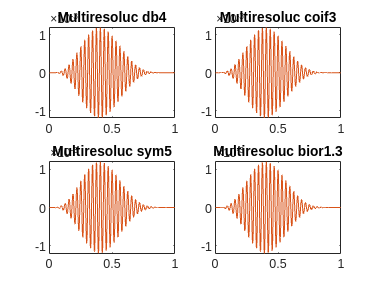

% a) Obtener las señales de aproximación y detalle A1 y D1

% Función
s = fx3;

% Daubechies
wdb4 = 'db4';
[Cdb4,Ldb4] = wavedec(s,1,wdb4);                         
A1_db4 = wrcoef('a',Cdb4,Ldb4,wdb4,1);
D1_db4 = wrcoef('d',Cdb4,Ldb4,wdb4,1);

% Coiflets
wcoif3 = 'coif3';                                      
[Ccoif3,Lcoif3] = wavedec(s,1,wcoif3);                                    
A1_coif3 = wrcoef('a',Ccoif3,Lcoif3,wcoif3,1);
D1_coif3 = wrcoef('d',Ccoif3,Lcoif3,wcoif3,1);

% Symlets
wsym5 = 'sym5';                                         
[Csym5,Lsym5] = wavedec(s,1,wsym5);                                        
A1_sym5 = wrcoef('a',Csym5,Lsym5,wsym5,1);
D1_sym5 = wrcoef('d',Csym5,Lsym5,wsym5,1);

% Biorthogonal   
wbior1_3 = 'bior1.3';
[Cbior1_3,Lbior1_3] = wavedec(s,1,wbior1_3);             
A1_bior1_3 = wrcoef('a',Cbior1_3,Lbior1_3,wbior1_3,1);
D1_bior1_3 = wrcoef('d',Cbior1_3,Lbior1_3,wbior1_3,1);



% b) Reconstruir la señal como s=A1 + D1

% Daubechies
R_db4 = A1_db4 + D1_db4;

% Coiflets
R_coif3 = A1_coif3 + D1_coif3;

% Symlets
R_sym5 = A1_sym5 + D1_sym5;

% Biorthogonal 
R_bior1_3 = A1_bior1_3 + D1_bior1_3;


% PLOTS
figure; 
subplot(2,2,1)
plot(x,s,x,R_db4); title('Multiresoluc db4')

subplot(2,2,2)
plot(x,s,x,R_coif3); title('Multiresoluc coif3')

subplot(2,2,3)
plot(x,s,x,R_sym5); title('Multiresoluc sym5')

subplot(2,2,4)
plot(x,s,x,R_bior1_3); title('Multiresoluc bior1.3')

**4) **$f (x) = 1(0,2 < x < 0,3) - 3(0,4 < x < 0,5) + 2(0,5 < x < 0,8)$

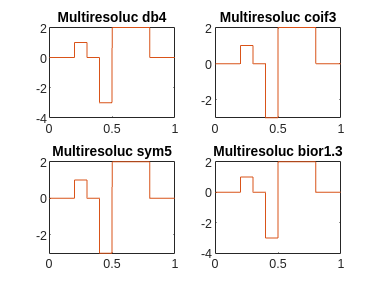

% a) Obtener las señales de aproximación y detalle A1 y D1

% Functción
s = fx4;

% Daubechies
wdb4 = 'db4';
[Cdb4,Ldb4] = wavedec(s,1,wdb4);                         
A1_db4 = wrcoef('a',Cdb4,Ldb4,wdb4,1);
D1_db4 = wrcoef('d',Cdb4,Ldb4,wdb4,1);

% Coiflets
wcoif3 = 'coif3';                                      
[Ccoif3,Lcoif3] = wavedec(s,1,wcoif3);                                    
A1_coif3 = wrcoef('a',Ccoif3,Lcoif3,wcoif3,1);
D1_coif3 = wrcoef('d',Ccoif3,Lcoif3,wcoif3,1);

% Symlets
wsym5 = 'sym5';                                         
[Csym5,Lsym5] = wavedec(s,1,wsym5);                                        
A1_sym5 = wrcoef('a',Csym5,Lsym5,wsym5,1);
D1_sym5 = wrcoef('d',Csym5,Lsym5,wsym5,1);

% Biorthogonal   
wbior1_3 = 'bior1.3';
[Cbior1_3,Lbior1_3] = wavedec(s,1,wbior1_3);             
A1_bior1_3 = wrcoef('a',Cbior1_3,Lbior1_3,wbior1_3,1);
D1_bior1_3 = wrcoef('d',Cbior1_3,Lbior1_3,wbior1_3,1);



% b) Reconstruir la señal como s=A1 + D1

% Daubechies
R_db4 = A1_db4 + D1_db4;

% Coiflets
R_coif3 = A1_coif3 + D1_coif3;

% Symlets
R_sym5 = A1_sym5 + D1_sym5;

% Biorthogonal 
R_bior1_3 = A1_bior1_3 + D1_bior1_3;


% PLOTS
figure; 
subplot(2,2,1)
plot(x,s,x,R_db4); title('Multiresoluc db4')

subplot(2,2,2)
plot(x,s,x,R_coif3); title('Multiresoluc coif3')

subplot(2,2,3)
plot(x,s,x,R_sym5); title('Multiresoluc sym5')

subplot(2,2,4)
plot(x,s,x,R_bior1_3); title('Multiresoluc bior1.3')

**5) **$f (x) = sign(\sin(12\pi x))$

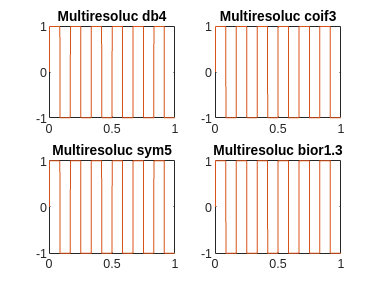

% a) Obtener las señales de aproximación y detalle A1 y D1

% Functción
s = fx5;

% Daubechies
wdb4 = 'db4';
[Cdb4,Ldb4] = wavedec(s,1,wdb4);                         
A1_db4 = wrcoef('a',Cdb4,Ldb4,wdb4,1);
D1_db4 = wrcoef('d',Cdb4,Ldb4,wdb4,1);

% Coiflets
wcoif3 = 'coif3';                                      
[Ccoif3,Lcoif3] = wavedec(s,1,wcoif3);                                    
A1_coif3 = wrcoef('a',Ccoif3,Lcoif3,wcoif3,1);
D1_coif3 = wrcoef('d',Ccoif3,Lcoif3,wcoif3,1);

% Symlets
wsym5 = 'sym5';                                         
[Csym5,Lsym5] = wavedec(s,1,wsym5);                                        
A1_sym5 = wrcoef('a',Csym5,Lsym5,wsym5,1);
D1_sym5 = wrcoef('d',Csym5,Lsym5,wsym5,1);

% Biorthogonal   
wbior1_3 = 'bior1.3';
[Cbior1_3,Lbior1_3] = wavedec(s,1,wbior1_3);             
A1_bior1_3 = wrcoef('a',Cbior1_3,Lbior1_3,wbior1_3,1);
D1_bior1_3 = wrcoef('d',Cbior1_3,Lbior1_3,wbior1_3,1);



% b) Reconstruir la señal como s=A1 + D1

% Daubechies
R_db4 = A1_db4 + D1_db4;

% Coiflets
R_coif3 = A1_coif3 + D1_coif3;

% Symlets
R_sym5 = A1_sym5 + D1_sym5;

% Biorthogonal 
R_bior1_3 = A1_bior1_3 + D1_bior1_3;


% PLOTS
figure; 
subplot(2,2,1)
plot(x,s,x,R_db4); title('Multiresoluc db4')

subplot(2,2,2)
plot(x,s,x,R_coif3); title('Multiresoluc coif3')

subplot(2,2,3)
plot(x,s,x,R_sym5); title('Multiresoluc sym5')

subplot(2,2,4)
plot(x,s,x,R_bior1_3); title('Multiresoluc bior1.3')